# Taller 1, punto 4: perceptron sobre las particiones de Iris

Se cargan las cuatro particiones que dejo T0_Dataset_train_test y se entrena el perceptron con varios alpha en cada una. Como la neurona es una sola, solo puede separar dos clases, asi que se arman dos problemas:

clear; close all; clc
load iris_splits.mat
if ~exist('informe/figuras', 'dir'), mkdir('informe/figuras'); end
if ~exist('informe/tablas', 'dir'),  mkdir('informe/tablas');  end

## Parametros

op.regla      = 3;
op.umbral     = 0;
op.salida     = [-1 1];
op.max_epocas = 200;
op.semilla    = 1;
alphas = [0.01 0.05 0.1 0.5 1];

problemas = {'A: setosa vs resto', 'B: versicolor vs virginica'};

## Entrenamiento en todas las particiones y todos los alpha

filas = {};
for pr = 1:2
    for k = 1:numel(S)
        % se arma el problema binario
        if pr == 1
            Xtr = S(k).Xtr;  ytr = S(k).ytr;  Xte = S(k).Xte;  yte = S(k).yte;
            dtr = ones(size(ytr)) * op.salida(1);  dtr(ytr == 1) = op.salida(2);
            dte = ones(size(yte)) * op.salida(1);  dte(yte == 1) = op.salida(2);
        else
            mtr = S(k).ytr ~= 1;  mte = S(k).yte ~= 1;
            Xtr = S(k).Xtr(mtr, :);  ytr = S(k).ytr(mtr);
            Xte = S(k).Xte(mte, :);  yte = S(k).yte(mte);
            dtr = ones(size(ytr)) * op.salida(1);  dtr(ytr == 2) = op.salida(2);
            dte = ones(size(yte)) * op.salida(1);  dte(yte == 2) = op.salida(2);
        end

        % escalado min-max con los valores del entrenamiento, como en la
        % clase de preprocesamiento. Los de test se escalan con los mismos
        % minimos y maximos.
        mn = min(Xtr); mx = max(Xtr);
        Xtr_s = (Xtr - mn) ./ (mx - mn);
        Xte_s = (Xte - mn) ./ (mx - mn);

        for a = alphas
            o = op; o.alpha = a;
            [w, b, info] = perceptron(Xtr_s, dtr, o);
            acc_tr = mean(predecir(Xtr_s, w, b, o.umbral, o.salida) == dtr);
            acc_te = mean(predecir(Xte_s, w, b, o.umbral, o.salida) == dte);
            filas(end+1, :) = {problemas{pr}, sprintf('%d-%d', round(100*S(k).p), round(100*(1-S(k).p))), ...
                a, info.epocas, info.convergio, 100*acc_tr, 100*acc_te}; %#ok<SAGROW>
        end
    end
end
R = cell2table(filas, 'VariableNames', ...
    {'Problema', 'Particion', 'Alpha', 'Epocas', 'Convergio', 'Exact_train', 'Exact_test'});
disp(R)

               Problema               Particion    Alpha    Epocas    Convergio    Exact_train    Exact_test
    ______________________________    _________    _____    ______    _________    ___________    __________

    {'A: setosa vs resto'        }    {'60-40'}    0.01       17        true            100            100  
    {'A: setosa vs resto'        }    {'60-40'}    0.05        5        true            100            100  
    {'A: setosa vs resto'        }    {'60-40'}     0.1        4        true            100            100  
    {'A: setosa vs resto'        }    {'60-40'}     0.5        2        true            100            100  
    {'A: setosa vs resto'        }    {'60-40'}       1        2        true            100            100  
    {'A: setosa vs resto'        }    {'70-30'}    0.01       15        true            100            100  
    {'A: setosa vs resto'        }    {'70-30'}    0.05        5        true            100            100  
    {'A: setosa vs

writetable(R, 'informe/tablas/perc_iris.csv');

## Resumen por problema y particion (promedio sobre los alpha)

Res = groupsummary(R, {'Problema', 'Particion'}, 'mean', {'Epocas', 'Exact_train', 'Exact_test'});
disp(Res)

               Problema               Particion    GroupCount    mean_Epocas    mean_Exact_train    mean_Exact_test
    ______________________________    _________    __________    ___________    ________________    _______________

    {'A: setosa vs resto'        }    {'60-40'}        5                6               100                100     
    {'A: setosa vs resto'        }    {'70-30'}        5              5.6               100                100     
    {'A: setosa vs resto'        }    {'80-20'}        5                6               100                100     
    {'A: setosa vs resto'        }    {'90-10'}        5                6               100                100     
    {'B: versicolor vs virginica'}    {'60-40'}        5            125.6            97.857             92.727     
    {'B: versicolor vs virginica'}    {'70-30'}        5              200            98.529             89.375     
    {'B: versicolor vs virginica'}    {'80-20'}        5              1

## Grafica: exactitud de test contra alpha

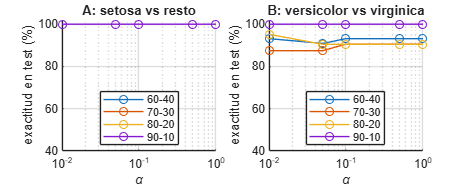

figure('Position', [100 100 950 380]);
for pr = 1:2
    subplot(1, 2, pr); hold on
    for k = 1:numel(S)
        etiqueta = sprintf('%d-%d', round(100*S(k).p), round(100*(1-S(k).p)));
        m = strcmp(R.Problema, problemas{pr}) & strcmp(R.Particion, etiqueta);
        plot(R.Alpha(m), R.Exact_test(m), '-o', 'DisplayName', etiqueta);
    end
    set(gca, 'XScale', 'log'); grid on; ylim([40 102]);
    xlabel('\alpha'); ylabel('exactitud en test (%)'); title(problemas{pr});
    legend('Location', 'best');
end
guardar_fig('perc_iris');

## Ver las dos clases del problema B en el plano petalo largo / petalo ancho

Aqui se ve por que no converge: las clases se pisan.

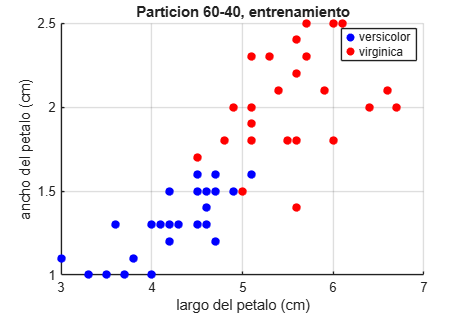

figure('Position', [100 100 600 400]); hold on
m2 = S(1).ytr == 2;  m3 = S(1).ytr == 3;
scatter(S(1).Xtr(m2, 3), S(1).Xtr(m2, 4), 40, 'b', 'filled');
scatter(S(1).Xtr(m3, 3), S(1).Xtr(m3, 4), 40, 'r', 'filled');
xlabel('largo del petalo (cm)'); ylabel('ancho del petalo (cm)'); grid on
legend('versicolor', 'virginica', 'Location', 'best');
title('Particion 60-40, entrenamiento');
guardar_fig('iris_versicolor_virginica');